# Code examples for MNC2

Ariadna Cortés Danés -- 2022-2023 Q2

clear all
close all
format long

### LU - factorization with partial pivoting

A = [1 0 1; 3 1 0; 0 0 1];
b = [1 1 -1]';

% LU factorization with partial pivoting
[P, L, U] = pplu(A);

%  [L, U] = milu(A) without pivoting

PA = LU factortization. P is the matrix storing the permutations aplied to A, L and U are the Lower and Upper matrixes. 

% Solve the system
x = plusolve(L, U, P, b)

x =    2.000000000000000
  -5.000000000000001
  -1.000000000000000


### Least Squares polynomial fitting (with Vandermonde)

f = @(x)  x.^2 -2        % the function to interpolate

f = function_handle with value:
    @(x)x.^2-2


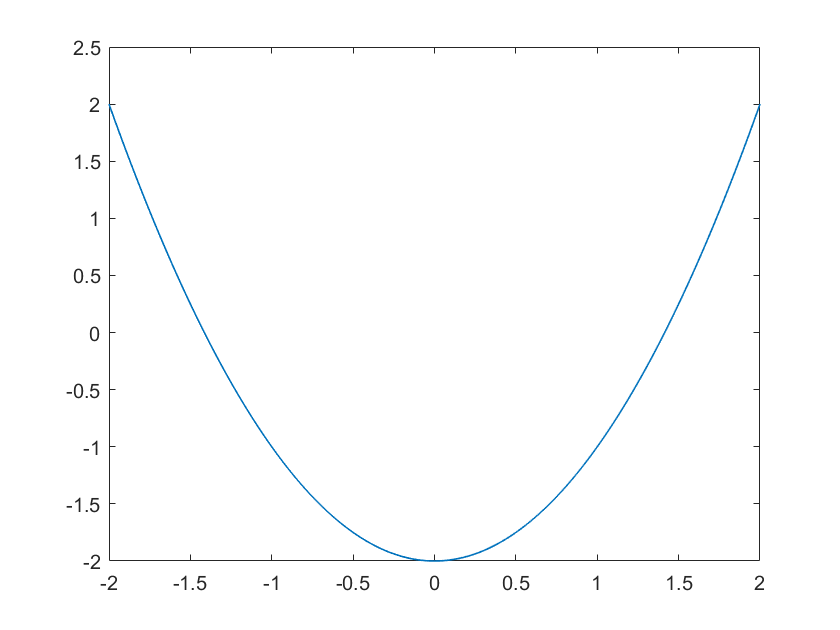

n = 25;                  % the number of points to do the interpolation
m = 10;                   % the degree of the interpoland

% Create n nodes
jj = 0:n;
xj = -1+2*jj/n;         %equispaced
% xj = cos(jj*pi/n);    %Chebyshev
 
% Create the vandermonde matrix of the equispaced nodes
V = fliplr(vander(xj));
V = V(:, 1:m+1);

% Solve the system to find the a_i coefficients of the polynomial interpolation 
fx = f(xj)';
UR = myqr(V);
a = qrsolve(UR,fx);

% Create the Vandermonde matrix for a mesh to evaluate the polynomial
mesh = linspace(-2,2,500);
X = fliplr(vander(mesh));
X = X(:, 1:m+1);

% Plot f(x) vs the polynomical approximation    
figure(1)
title('Least Squares Polynomial Fit', 'Interpreter', 'latex')
subtitle('With equispaced nodes', 'Interpreter', 'latex')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$f(x)$', 'Interpreter', 'latex')
plot(mesh, X*a, 'Linewidth',0.8)   

### Least Squares trigonometric fitting (with Vandermonde)

% The data to fit 
hora = [8*60+14, 7*60+49, 7*60+2, 6*60+6, 5*60+13, 4*60+36, 4*60+29, 4*60+51, 5*60 + 27, 6*60+3, 6*60+42, 7*60+24, 8*60+2];
dia = [1 29 57 85 113 141 169 197 225 253 281 309 337];
dia = 2*pi*dia/max(dia);

plot(dia, hora, '--k','LineWidth', 0.3)
title('Hora de sortida del sol', 'Interpreter','latex')
xlabel("Dia de l'any", 'Interpreter','latex')
ylabel("Minut de sortida del sol",'Interpreter','latex')
hold on

% Data fit with T(t) = a0 + a1 sin(t) + a2 cos(t) = V(t)*a
sint = sin(dia);
cost = cos(dia);

V = [ones(size(dia)); sint; cost]'      % matrix such that Hora = V*a

V =    1.000000000000000   0.018643386619389   0.999826196963932
   1.000000000000000   0.514727291096737   0.857353961791870
   1.000000000000000   0.873689091856081   0.486484707644235
   1.000000000000000   0.999902234553183  -0.013982894391036
   1.000000000000000   0.859743843652124  -0.510725487226036
   1.000000000000000   0.490551775036032  -0.871412047202125
   1.000000000000000  -0.009322098370745  -0.999956548296958
   1.000000000000000  -0.506712587348964  -0.862115046743831
   1.000000000000000  -0.869116070276587  -0.494608184714913
   1.000000000000000  -0.999989137015237   0.004661099818829


a = V\hora'

a = 	1.0e+02 *

   3.705755573545563
   0.032280070598733
   1.041316939859847


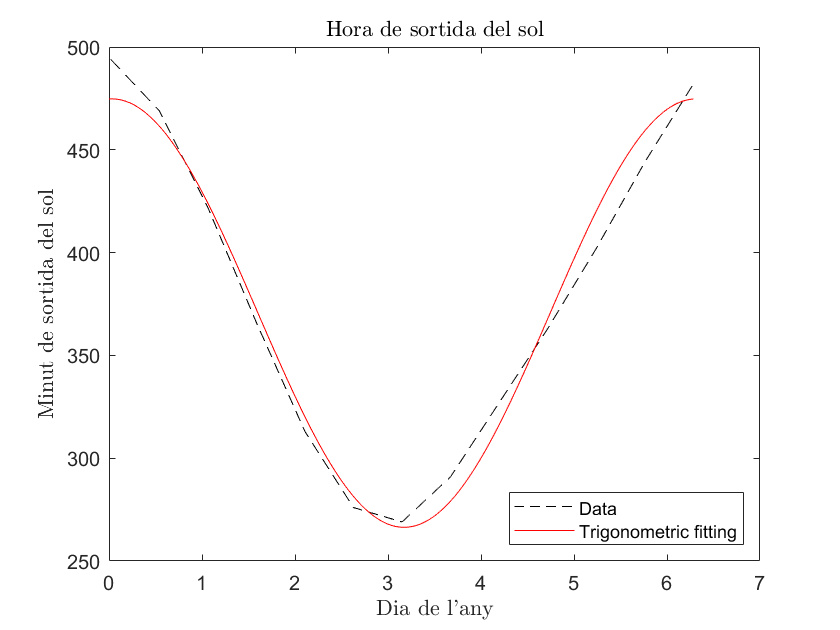


% Mesh
mesh = linspace(0,2*pi, 365);
sint_mesh = sin(mesh);
cost_mesh = cos(mesh);

V_mesh = [ones(size(mesh)); sint_mesh; cost_mesh]';     %vandermonde to evaluate the mesh
expected_hour = V_mesh*a;

plot(mesh, expected_hour, '-r')
legend('Data','Trigonometric fitting', "Location",'southeast')


% Error :)
e = sum((hora - a(1) - a(2)*sint - a(3)*cost).^2)

e =      1.450922512688513e+03


### QR decomposition

A = [1 0 1; 3 1 0; 0 0 1];  % as before
b = [1 1 -1]';

UR = myqr(A)

UR =   -3.162277660168379  -0.948683298050514  -0.316227766016838
   0.720759220056126  -0.316227766016838   0.948683298050514
                   0                   0   1.000000000000000


x = qrsolve(UR,b)

x =    2.000000000000000
  -4.999999999999999
  -1.000000000000000


### QR decomposition with CGS algorithm

A = [1 0 1; 3 1 0; 0 0 1];  % as before
b = [1 1 -1]';

[Q, R, S] = mycgs(A)

Q =    0.316227766016838  -0.948683298050514   0.000000000000000
   0.948683298050514   0.316227766016838   0.000000000000000
                   0                   0   1.000000000000000


R =    3.162277660168380   0.948683298050514   0.316227766016838
                   0   0.316227766016838  -0.948683298050514
                   0                   0   1.000000000000000


S = 	1.0e+-15 *

                   0   0.083266726846887   0.298420844829020
                   0                   0  -0.017554167342883
                   0                   0                   0


% if Q was really orthogonal, then Q' = Q^(-1) meaning Q*Q' = I, meaning
% norm(Q*Q' - I) --> 0 
e = norm(Q*Q'-eye(size(Q)))

e =      4.480590720603394e-16



x = qrsolve2(Q,R,b)

x =    1.999999999999999
  -4.999999999999998
  -1.000000000000000


### QR decomposition with GSR algorithm

A = [1 0 1; 3 1 0; 0 0 1];  % as before
b = [1 1 -1]';

[Q, R] = gsr(A);
x = qrsolve2(Q,R,b)

x =    2.000000000000000
  -4.999999999999999
  -1.000000000000000


### Krylov solver (Arnoldi Method)

%[x, k] = mygmres(@Afun, b, tol, m_max);
[x, k] = mygmres(@Afun, b, eps/2, 50)

'Afun' is used in Largest Singular Values Using Function Handle.

Error in mygmres (line 17)
        Q(:, k+1) = feval(Afun, Q(:, k));       % q_{k+1} = Aq_k


% function Ax = Afun(x)
%     y1 = x(1)+ x(3);
%     y2 = 3*x(1) + x(2);
%     y3 = x(3);
%     % yn = ...
%     Ax = [y1 y2 y3];
% end

### Newton in n dimensions

%[XK,resd,it] = newtonn(x0,tol,itmax,fun)

fun = @funn;
[xk,resd,it] = newtonn([0.5 0.25]',eps,50,fun)

xk =    0.500000000000000  -0.046302492577202   0.000033118022846  -0.000000000000012                   0                   0
   0.250000000000000   1.046302492577202   0.999966881977154   1.000000000000012   1.000000000000000   1.000000000000000


resd =    0.540692932324744   0.540692932324744   0.046285949537683   0.000033118022840   0.000000000000012                   0


it =      6


x = xk(:,end)

x =      0
     1



% function Y = funn(X)
%     y1 = X(1) + X(2)-1;
%     y2 = sin(X(1));
%     % yn = ...
%     Y = [y1 y2]';
% end